# PROF. AMBROSINO R.___ESAME___11/03/2026___SALVATORE_RAIOLA_DE6000008

clear; close all; clc;

## 0)  DEFINIZIONI

#### Variabili Simboliche 

syms x theta dx dtheta ddx ddtheta u real;

#### Parametri

M = 0.8; 
m = 0.2;
l = 0.3;
I = 0.006;
b = 0.08;
c = 0.002;
g = 9.81;
J = I + m*l^2;

#### I-S-U

% Stato
X = [x;
     dx;
     theta;
     dtheta];

% Uscita
y = [x;
     theta];

#### Modello Dinamico

eq_1_sym = (M+m)*ddx + m*l*cos(theta)*ddtheta == u - b*dx + m*l*sin(theta)*dtheta^2;
eq_2_sym = m*l*cos(theta)*ddx + J*ddtheta == -c*dtheta + m*g*l*sin(theta);

eqs = [eq_1_sym;
       eq_2_sym];

sol = solve(eqs, [ddx, ddtheta], "ReturnConditions",true);

% dX/dt
f = [dx;
     sol.ddx;
     dtheta;
     sol.ddtheta];
% y
g = y;

A_sym = jacobian(f,X);
B_sym = jacobian(f,u);
C_sym = jacobian(g,X);
D_sym = jacobian(g,u);

n = size(A_sym,1);
m = size(B_sym,2);

## 1)  PUNTI DI EQUILIBRIO E LINEARIZZAZIONE

### 1.1)  Punti di Equilibrio per u=0

eq_1_peql = subs(eq_1_sym, [dx, dtheta, ddx, ddtheta, u], [0, 0, 0, 0, 0]) == 0;
eq_2_peql = subs(eq_2_sym, [dx, dtheta, ddx, ddtheta, u], [0, 0, 0, 0, 0]) == 0;

eqs_peql = [eq_1_peql;
            eq_2_peql];

peql = solve(eqs_peql, [x,theta], "ReturnConditions",true);

x_star = peql.x;
theta_star = peql.theta;

dx_star = 0;
dtheta_star = 0;

disp(table(x_star, dx_star, theta_star, dtheta_star));

    x_star    dx_star    theta_star    dtheta_star
    ______    _______    __________    ___________

      y          0          pi*k            0     



### 1.2)  Modello linearizzato nell'intorno di X*

X_star = [0;
          0;
          0;
          0];

A = double(subs(A_sym, [X; u], [X_star; 0]));
B = double(subs(B_sym, [X; u], [X_star; 0]));
C = double(subs(C_sym, [X; u], [X_star; 0]));
D = double(subs(D_sym, [X; u], [X_star; 0]));

sys_lin = ss(A, B, C, D)


sys_lin =
 
  A = 
             x1        x2        x3        x4
   x1         0         1         0         0
   x2         0  -0.09412    -1.731  0.005882
   x3         0         0         0         1
   x4         0    0.2353     28.85  -0.09804
 
  B = 
           u1
   x1       0
   x2   1.176
   x3       0
   x4  -2.941
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


### 1.3)  Osservabilità e controllabilità del sistema 

#### Controllabilità

if rank(ctrb(A,B)) == n
    disp('il sistema è completamente Controllabile');
else
    disp('il sistema NON è completamente Controllabile');
end

il sistema è completamente Controllabile


#### Osservabilità

if rank(obsv(A,C)) == n
    disp('il sistema è completamente Osservabile');
else
    disp('il sistema NON è completamente Osservabile');
end

il sistema è completamente Osservabile


## 2)  ASSEGNAMENTO AUTOVALORI

#### Specifiche

% Stato inziale 
x0 = 0.1;
theta0 = deg2rad(15);

X0 = [x0;
      0;
      theta0;
      0];

% Autovalori desiderati
eig_des = [-2, -2.5, -3, -3.5];

#### Sintesi 

K_EIG = place(A, B, eig_des)

K_EIG =    -1.8196   -2.8502  -25.8452   -4.8147


A_cl = A - B * K_EIG;

% Mostra gli autovalori effettivi
disp('Autovalori a ciclo chiuso:');

Autovalori a ciclo chiuso:


disp(eig(A_cl));

   -3.5000
   -3.0000
   -2.5000
   -2.0000



#### Parametri Simulink

C_tot = eye(4);

D_tot = zeros(4,1);

#### Verifica Simulazione

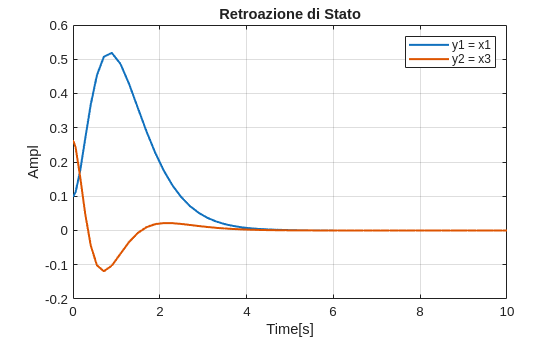

% Plot MATLAB
out = sim('Verifica_EIG_20022026.slx');
y1_eig = out.y1.Data;
y2_eig = out.y2.Data;
time = out.y1.Time;

figure
plot(time, y1_eig, "LineWidth", 1.5);
grid on
hold on 
plot(time, y2_eig, "LineWidth", 1.5);
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x1', 'y2 = x3');
title('Retroazione di Stato');

**Lo schema Simulink è consultabile dal seguente link**

Schema Simulink:  [Verifica_EIG](matlab:open_system('Verifica_EIG_20022026.slx'))

## 3)  APPROCCIO ALLA LYAPUNOV

#### Specifiche

% Riferimento
X_ref = [0.2;
         0;
         0;
         0];

#### Risoluzione LMI con cvx

cvx_clear;
cvx_begin sdp quiet
    cvx_precision high
    variable Q(n,n) symmetric
    variable L(m,n)

    minimize(0);

    subject to
    Q >= (1e-6)*eye(n);
    A*Q + Q*A' + B*L + L'*B' <= (1e-6)*eye(n);
cvx_end;

K_LMI = -L/Q

K_LMI =    -1.8931   -2.3611  -33.4546   -4.3181


sys_cl = ss((A-B*K_LMI), B, C_tot, D_tot);
gain = dcgain(sys_cl);
N = pinv(gain)

N =    -1.8931         0         0         0


#### Verifica Simulazione

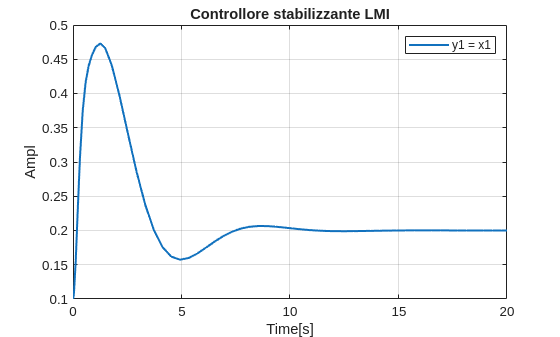

% Plot MATLAB
out = sim('Verifica_LMI_20022026.slx');
y1_lmi = out.y1.Data;
time = out.y1.Time;

figure
plot(time, y1_lmi, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x1');
title('Controllore stabilizzante LMI');

**Lo schema Simulink è consultabile dal seguente link**

Schema simulink:  [Verifica_LMI](matlab:open_system('Verifica_LMI_20022026.slx'))

## 4)  CONTROLLO LQR CON AZIONE INTEGRALE 

#### Specifiche

% Riferimento
x_ref_lqr = 0.2;

X_ref_LQR = [x_ref_lqr;
             0;
             0;
             0];

% Tempo di Assestamento
Ts = 5;

#### Sistema aumentato

C_LQR = [1, 0, 0, 0];

p_aug = size(C_LQR,1);

A_aug = [A, zeros(n,p_aug);
         -C_LQR, zeros(p_aug, p_aug)];

B_aug = [B;
         zeros(p_aug, m)];

n_aug = size(A_aug,1);

C_aug = [eye(n), zeros(n,1)];

D_aug = 0;

% shift dello spettro di A per rispettare la specifica sul Ts
alpha = 4/Ts;
A_hat = A_aug - alpha*eye(n_aug);
eig(A_hat)

ans =    -0.8000
   -0.8000
    4.5158
   -6.2280
   -0.8800



sys_aug = ss(A_hat, B_aug, C_aug, D_aug)


sys_aug =
 
  A = 
             x1        x2        x3        x4        x5
   x1      -0.8         1         0         0         0
   x2         0   -0.8941    -1.731  0.005882         0
   x3         0         0      -0.8         1         0
   x4         0    0.2353     28.85    -0.898         0
   x5        -1         0         0         0      -0.8
 
  B = 
           u1
   x1       0
   x2   1.176
   x3       0
   x4  -2.941
   x5       0
 
  C = 
       x1  x2  x3  x4  x5
   y1   1   0   0   0   0
   y2   0   1   0   0   0
   y3   0   0   1   0   0
   y4   0   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.


#### Sintesi LQR

Q_bar = 1;
Q = C_aug'*Q_bar*C_aug + blkdiag(zeros(n,n), 100)

Q =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0   100



R = eye(m);

[K_LQR,~,~] = lqr(sys_aug, Q, R)

K_LQR =    -4.4468   -3.4463  -27.7599   -5.3843    3.1473


K_LQR_x = K_LQR(:, 1:n)

K_LQR_x =    -4.4468   -3.4463  -27.7599   -5.3843


K_LQR_i = K_LQR(:, n+1:end)

K_LQR_i = 3.1473

#### Verifica Simulazione

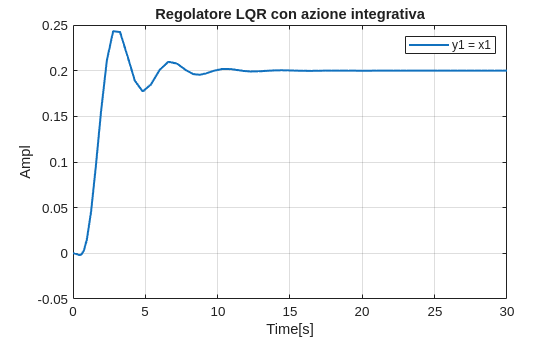

% Plot MATLAB
out = sim('Verifica_LQR_20022026.slx');
y1_lqr = out.y1.Data;
time = out.y1.Time;

figure
plot(time, y1_lqr, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x1');
title('Regolatore LQR con azione integrativa');

**Lo schema Simulink è consultabile dal seguente link**

Schema simulink:  [Verifica_LQR](matlab:open_system('Verifica_LQR_20022026.slx'))

## 5)  CONTROLLO LQG CON AZIONE INTEGRALE

#### Specifiche

Q_v = 1e-4;
R_v = 1e-3;

#### Matrici di Covarianza 

Q_cov = Q_v*eye(n);
R_cov = R_v*eye(2);

#### Sintesi

[P_kalman,~,~] = care(A', C', Q_cov, R_cov);

% Guadagno
L_kalman = P_kalman*C'/R_cov

L_kalman =     0.8089   -0.5403
    0.4231   -3.3048
   -0.5403   10.6091
   -2.8642   56.3727


A_kalman = A-L_kalman*C;
B_kalman = [B, L_kalman];
C_kalman = eye(n);
D_kalman = zeros(n,3);


sys_kalman = ss(A_kalman, B_kalman, C_kalman, D_kalman)


sys_kalman =
 
  A = 
             x1        x2        x3        x4
   x1   -0.8089         1    0.5403         0
   x2   -0.4231  -0.09412     1.574  0.005882
   x3    0.5403         0    -10.61         1
   x4     2.864    0.2353    -27.52  -0.09804
 
  B = 
            u1       u2       u3
   x1        0   0.8089  -0.5403
   x2    1.176   0.4231   -3.305
   x3        0  -0.5403    10.61
   x4   -2.941   -2.864    56.37
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
   y3   0   0   0
   y4   0   0   0
 
Continuous-time state-space model.


eig(A_kalman)

ans =   -0.4308 + 0.3636i
  -0.4308 - 0.3636i
  -5.2089 + 0.0000i
  -5.5397 + 0.0000i


#### Verifica Simulazione

Schema Simulink:  [Verifica_LQG](matlab:open_system('Verifica_LQG_20022026.slx'))